% This code is the implementation of the Extended Kalman Filter described
% in “A Filtering Approach for Image-Guided Surgery With a Highly Articulated Surgical Snake Robot”
% by Stephen Tullyand Howie Choset

% All variables are same as used in the paper “A Filtering Approach for Image-Guided Surgery With a Highly Articulated Surgical Snake Robot”

% Extended Kalman Filter_Shape Estimation_Medical Snake 
syms alphanot betanot gammanot xnot ynot znot theta phi L 

## Check points for functions

% Run this first while running code - input will be delc1 and delc2 which
% in real will be obtained from encoders
delc1 = [0 0.5 0.3 0];                              % Change these values according to whether after 1st advance you are advancing or steering
delc2 = [0 0.9 0.5 0];                              % Right now since the 2nd values in both delc1 and delc2 are non zero it means first we advance then we steer
Cr = 1.5;
[thetastr, phistr] = steerang(5, delc1, delc2,Cr);
[delthetastr, delphistr] = delsteerang(5,thetastr, phistr);

% Defining values for link length (L), number of links (n), pose of first
% link (alphanot,betanot,gammanot,xnot,ynot,znot)
L = 10;
alphanot = 0;
betanot = 0;
gammanot = 0;
xnot = 4;
ynot = 5;
znot = 6;
n = 5;

%% While actually running the code, use the theta = thetastr and phi = phistr
% the values will be obtained from function "steerang"
theta = [0 1.2107 1.1905 0];
phi = [0 0.12405 0.5691 0];
Tnot = tnot(alphanot,betanot,gammanot,xnot,ynot,znot);
Tang = tang(n,theta, phi);
Tadv = tadv(L);
[T, pk, anglek, hxk] = t(n, Tnot, Tang, Tadv);
hxk

hxk = hxk(:,:,1) =

     4
     5
     6
     0
     0


hxk(:,:,2) =

    14
     5
     6
     0
     0


hxk(:,:,3) =

   17.4966
    2.1104
   -2.9120
   -0.6906
    1.1000


hxk(:,:,4) =

   15.9552
    9.5339
   -9.4324
    1.7755
    0.7103


hxk(:,:,5) =

   14.4138
   16.9574
  -15.9528
    1.7755
    0.7103



% State vector 
XK = xk(n,xnot, ynot, znot, alphanot, betanot, gammanot, theta, phi)

XK =     4.0000    5.0000    6.0000         0         0         0         0         0    0.1240    1.2107    0.5691    1.1905         0         0


% Advance function
advance = adv_motion(2,XK);

% Steer function
xk_steer = steer_motion(3,XK,delthetastr, delphistr)

xk_steer =     4.0000
    5.0000
    6.0000
         0
         0
         0
         0
         0
    1.2405
    1.2107



% EKF Algorithm initial covariance matrix
v = 0.5;
V = [v v v v v];
Rcov = diag(V);
sigma2 = v;
z5x1 = zeros(5,1);
z1x5 = zeros(1,5);
P00 = [Rcov z5x1; z1x5 sigma2];

## For 1st advance function, i.e. 2 links out

% Computing Jacobians F
syms Xnot Ynot Znot Alphanot Betanot Gammanot
% Xnot Ynot Znot Alphanot Betanot Gammanot we obtain directly from EM
% sensor
f1 = [Xnot Ynot Znot Alphanot Betanot Gammanot 0 0];
x00 = [Xnot Ynot Znot Alphanot Betanot Gammanot];
F1 = jacobian(f1,x00);
F1t = transpose(F1);

% Computing Jacobians H
% The measurement model h(xk) is drawn from the matrix T
syms x1T y1T z1T alpha1T beta1T gamma1T Theta1 Phi1
h1 = [x1T y1T z1T alpha1T beta1T];      % Numerically h1 = hxk(:,:,1)
x10sym = [x1T y1T z1T alpha1T beta1T gamma1T Phi1 Theta1];
H1 = jacobian(h1, x10sym);
H1t = transpose(H1);

%% Prediction
% Computing predicted State vector Covariance matrices for next steps
x10 = adv_motion(2,XK);
P10 = F1*P00*F1t;

%% Update
% Defining sensor measurements which we directly get from EM sensor
% Currently taken random values close to hxk
z1 = [4.2 5 6.1 0.01 0]';

% Defining certain variables for EKF 
y1 = z1 - [hxk(:,:,1)];
S1 = H1*P10*H1t;
S1invs = inv(S1);

% Kalman Gain
K1 = P10*H1t*S1invs;

% Computing updated State vector Covariance matrices
x11 = double(x10 + K1*y1)

x11 =     4.2000
    5.0000
    6.1000
    0.0100
         0
         0
         0
         0


P11 = (eye(8) - K1*H1)*P10;

## For 2nd advance function, i.e. 3 links out

% % Computing Jacobians F
% syms Xnot Ynot Znot Alphanot Betanot Gammanot Phi1 Theta1 
% % Xnot Ynot Znot Alphanot Betanot Gammanot we obtain directly from EM
% % sensor
% f2 = [Xnot Ynot Znot Alphanot Betanot Gammanot 0 0 0 0];
% x11sym = [Xnot Ynot Znot Alphanot Betanot Gammanot Phi1 Theta1];
% F2 = jacobian(f2,x11sym);
% F2t = transpose(F2);
% 
% % Computing Jacobians H
% % The measurement model h(xk) is drawn from the matrix T
% syms x2T y2T z2T alpha2T beta2T gamma2T Phi1 Theta1 Phi2 Theta2
% h2 = [x2T y2T z2T alpha2T beta2T];      % Numerically h2 = hxk(:,:,2)
% x11syms = [x2T y2T z2T alpha2T beta2T gamma2T Phi1 Theta1 Phi2 Theta2];
% H2 = jacobian(h2, x11syms);
% H2t = transpose(H2);
% 
% %% Prediction
% % Computing predicted State vector Covariance matrices for next steps
% x21 = adv_motion(3,XK)
% P21 = F2*P11*F2t
% 
% %% Update
% % Defining sensor measurements which we directly get from EM sensor
% % Currently taken random values close to hxk
% z2 = [13.98 4.99 6.2 0 0.02]'; 
% 
% % Defining certain variables for EKF 
% y2 = z2 - [hxk(:,:,2)];
% S2 = H2*P21*H2t;
% S2invs = inv(S2);                       % Since inverse in gng to infinity we neglect it. The main reason for this is we have chosen random values for initialization.
% 
% % Kalman Gain
% K2 = P21*H2t;
% 
% % Computing updated State vector Covariance matrices
% x22 = double(x21 + K2*y2)
% P22 = (eye(10) - K2*H2)*P21;

## For Steer Function - 3 links out, 1st advance then steer

% Computing Jacobians F
syms Xnot Ynot Znot Alphanot Betanot Gammanot Phi1 Theta1 Phi2 Theta2
% Xnot Ynot Znot Alphanot Betanot Gammanot we obtain directly from EM
% sensor
f2 = [Xnot Ynot Znot Alphanot Betanot Gammanot Phi1 Theta1 Phi2 Theta2];
x11sym = [Xnot Ynot Znot Alphanot Betanot Gammanot Phi1 Theta1];
F2 = jacobian(f2,x11sym);
F2t = transpose(F2);

% Computing Jacobians H
% The measurement model h(xk) is drawn from the matrix T
syms x2T y2T z2T alpha2T beta2T gamma2T Phi1 Theta1 Phi2 Theta2
h2 = [x2T y2T z2T alpha2T beta2T];      % Numerically h2 = hxk(:,:,2)
x11syms = [x2T y2T z2T alpha2T beta2T gamma2T Phi1 Theta1 Phi2 Theta2];
H2 = jacobian(h2, x11syms);
H2t = transpose(H2);

% Prediction
% Computing predicted State vector Covariance matrices for next steps
x21 = steer_motion(3,XK,delthetastr, delphistr)

x21 =     4.0000
    5.0000
    6.0000
         0
         0
         0
         0
         0
    1.2405
    1.2107


P21 = F2*P11*F2t;

% Update
% Defining sensor measurements which we directly get from EM sensor
% Currently taken random values close to hxk
z2 = [17 2.4 -3.1 -0.7 1.1]'; 

% Defining certain variables for EKF 
y2 = z2 - [hxk(:,:,2)];
S2 = H2*P21*H2t;
S2invs = inv(S2);

% Kalman Gain
K2 = P21*H2t;

% Computing updated State vector Covariance matrices
x22 = double(x21 + K2*y2);

x22 =     4.0000
    5.0000
    6.0000
         0
         0
         0
         0
         0
    1.2405
    1.2107


P22 = (eye(10) - K2*H2)*P21;

## Plotting the predicted and EKF updated state vector

% For 1st Advance
figure(1)
hold on
l = [0 1 2 3 4 5 6 7]

l =      0     1     2     3     4     5     6     7


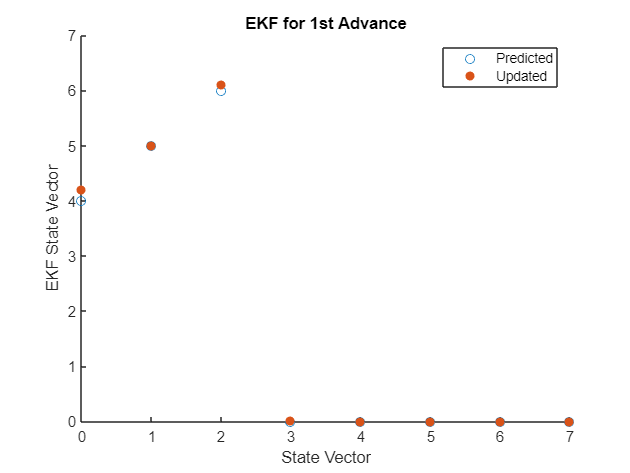

scatter(l, x10)
scatter(l,x11,'filled')
xlabel('State Vector')
ylabel('EKF State Vector')
legend('Predicted', 'Updated')
title('EKF for 1st Advance')

% For 2nd Advance
figure(2)
hold on
ll = [0 1 2 3 4 5 6 7 8 9]
scatter(ll, x21)
scatter(ll,x22,'filled')
xlabel('State Vector')
ylabel('EKF State Vector')
legend('Predicted', 'Updated')
title('EKF for 2nd Advance')

% For 2nd Steer
figure(2)
hold on
ll = [0 1 2 3 4 5 6 7 8 9]

ll =      0     1     2     3     4     5     6     7     8     9


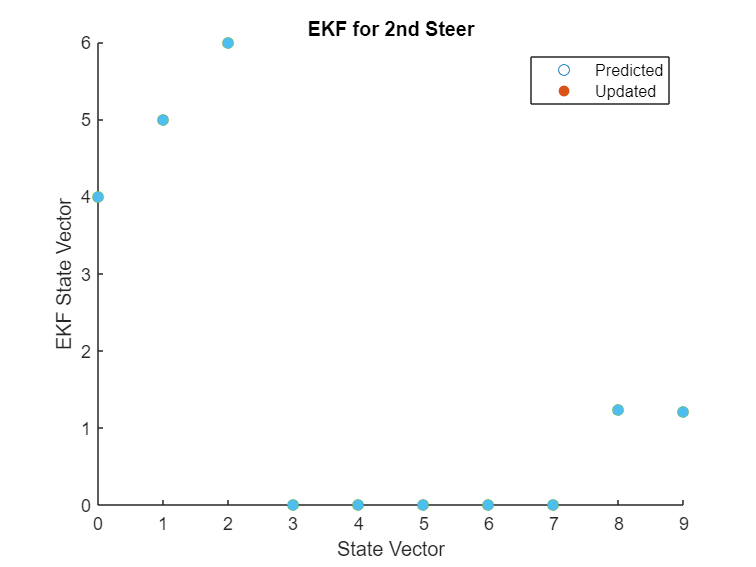

scatter(ll, x21)
scatter(ll,x22,'filled')
xlabel('State Vector')
ylabel('EKF State Vector')
legend('Predicted', 'Updated')
title('EKF for 2nd Steer')

#### % Defining functions for Matrices

function Rz = rz(x)
Rz = [cos(x) -sin(x) 0; sin(x) cos(x) 0; 0 0 1];
end

function Ry = ry(x)
Ry = [cos(x) 0 sin(x); 0 1 0; -sin(x) 0 cos(x)];
end

function Rx = rx(x)
Rx = [1 0 0; 0 cos(x) -sin(x); 0 sin(x) cos(x)];
end

function Tnot = tnot(alphanot,betanot,gammanot,xnot,ynot,znot)          % Transformation Matrix for proximal link
Rnot = rz(alphanot)*ry(betanot)*rx(gammanot);
Pnot = [xnot; ynot; znot];
Tnot = [Rnot Pnot; 0 0 0 1];
end

function Tang = tang(n,theta,phi)                                       % Transformation Matrix for angle
Tang = zeros(4,4,n-1);
R = zeros(3,3,n-1);
for i = 1:n-1
R(:,:,i) = rx(theta(:,i))*ry(phi(:,i))*rz(-theta(:,i));
P = [0; 0; 0];
Tang(:,:,i) = [R(:,:,i) P; 0 0 0 1];
end
end

function Tadv = tadv(L)
Tadv = [1 0 0 L; 0 1 0 0; 0 0 1 0; 0 0 0 1];
end

function XK = xk(n,xnot, ynot, znot, alphanot, betanot, gammanot, theta, phi)
XK_ini = [xnot, ynot, znot, alphanot, betanot, gammanot];
for i = 1:n-1
    XK_next = [phi(:,i) theta(:,i)];
    XK_ini = [XK_ini XK_next];
end
XK = XK_ini;
end

function [T, pk, anglek, hxk] = t(n, Tnot, Tang, Tadv)
T = zeros(4,4,n-1);
pk = zeros(1,3,n);
anglek = zeros(1,3,n);
hxk = zeros(5,1,n);
for i = 2:n    
    T(:,:,1)  = Tnot; 
    T(:,:,i) = T(:,:,i-1)*Tang(:,:,i-1)*Tadv;
end
for k = 1:n
    pk(:,:,k) = (T(1:3,4,k))';
    anglek(:,:,k) = rotm2eul(T(1:3,1:3,k));
    hxk(:,:,k) = [pk(:,:,k) anglek(:,1:2,k)]';
end
end

function [thetastr, phistr] = steerang(n, delc1, delc2,Cr)                     % Defining steering angles only for distal link using cable lengths
thetastr = zeros(1,1,n-1);                                                     % This function will output thetastr and phistr only for distal link at different timesteps!
phistr = zeros(1,1,n-1);
for i = 1:n-1
    if delc1(:,i) == 0 || delc2(:,i) == 0
        thetastr(:,:,i) = 0;
        phistr(:,:,i) = 0;
    else
    thetastr(:,:,i) = atan(((sqrt(3))*(2*delc2(:,i) + delc1(:,i)))/(3*delc1(:,i)));
    phistr(:,:,i) = norm(asin((-delc1(:,i))/(Cr*cos(thetastr(:,i)))));
    end
end
end

function [delthetastr, delphistr] = delsteerang(n,thetastr, phistr)            % Defining change in steering angles only for distal link using cable lengths
delthetastr = zeros(1,1,n-2);                                                  % This function will output change in thetastr and phistr only for distal link at different timesteps!
delphistr = zeros(1,1,n-2);
for i = 1:n-2
    delthetastr(:,:,i) = thetastr(:,:,i+1) - thetastr(:,:,i);
    delphistr(:,:,i) = phistr(:,:,i+1) - phistr(:,:,i);
end
end

function advance = adv_motion(numlinks,XK)   % Advance function 
xk_adv = XK(:,1:(6 + 2*numlinks-4));
advance = [xk_adv 0 0]';
end

function xk_steer = steer_motion(numlinks,XK,delthetastr, delphistr)   % Steer function
xk_steer_ini = XK(:,1:(6 + 2*numlinks-4));
xk_steer_pre = [xk_steer_ini 0 0];
m = size(xk_steer_ini);
z = zeros(m);
xk_steer_post = [z, delphistr(numlinks-2), delthetastr(numlinks-2)];
xk_steer_dash = xk_steer_pre + xk_steer_post;
xk_steer = xk_steer_dash';
end


